# Experiment with Focus Stacking

Experiment with focus stacking using our cp (Computational Photography) classes. Eventually add object and camera motion.

## Create a pbrt scene we can use

Using pbrt lets us get the highest-fidelity rendering. We use its lens model to get realistic depth and occlusion rendering.

ieInit();
setpref('ISET', 'fast_num2string', true); % use faster piWrite
sceneLuminance = 200;
numRays = 256;
filmResolution = 1024;

sceneChoice = "Cornell Box with Bunny";
apertureDiameter = 6;% in mm

% for legacy reasons, scenes don't have a uniform naming scheme,
% so we map the user's choice to the appropriate options
if strcmp(sceneChoice, "Cornell Box with Bunny")
    scenePath = 'Cornell_BoxBunnyChart';        
    sceneName = 'cornell box bunny chart';
elseif strcmp(sceneChoice, "CornellBoxReference")
    scenePath = "CornellBoxReference";
    sceneName = "CornellBoxReference";
else
    scenePath = 'ChessSet';
    sceneName = 'chessSet';
end

pbrtCPScene = cpScene('pbrt', 'scenePath', scenePath, 'sceneName', sceneName, ...
    'resolution', [filmResolution filmResolution], ...
    'numRays', numRays, 'sceneLuminance', sceneLuminance, ...
    'lensFile','wide.40deg.6.0mm.json',...
    'apertureDiameter', apertureDiameter); % realistic camera needs .dat

Read 1 materials.
Read 1 textures.
***Scene parsed.



pinholeCPScene = cpScene('pbrt', 'scenePath', scenePath, 'sceneName', sceneName, ...
    'resolution', [filmResolution filmResolution], ...
    'numRays', numRays, 'sceneLuminance', sceneLuminance);

Read 1 materials.
Read 1 textures.
***Scene parsed.



if strcmp(sceneChoice, "CornellBoxReference")
    bunny = load('bunny.mat');
    [~, bunny_id] = pbrtCPScene.thisR.set('asset',1, 'add', bunny.assetTree.Node{1});
    pbrtCPScene.thisR.set('material', 'add', bunny.matList{1});
    
    [~, bunny_id] = pinholeCPScene.thisR.set('asset',1, 'add', bunny.assetTree.Node{1});
    pinholeCPScene.thisR.set('material', 'add', bunny.matList{1});
    
    % in case bunny is out of our frame
    pinholeCPScene.thisR.set('asset', bunny_id, 'translate', [0 .1 0]);
    pbrtCPScene.thisR.set('asset', bunny_id, 'translate', [0 .1 0]);
    %if you want object motion
    %pbrtCPScene.objectMotion = {{bunny_id, [0 .1 0], [0 0 0]}};

    % now calculate the distance of the bunny
    bPos = pbrtCPScene.thisR.recipeGet('asset', bunny_id, 'world position');
    cPos = pbrtCPScene.thisR.lookAt.from;
    
    bDistance = sum((bPos-cPos).^2)^.5;
    
    mcc = load('mccCB.mat');
    [~, mcc_id] = pbrtCPScene.thisR.set('asset',1, 'add', mcc.assetTree.Node{1});
    pbrtCPScene.thisR.set('material', 'add', mcc.matList{1});
    %pbrtCPScene.thisR.set('asset', mcc_id, 'world position', [0, 1, 1]);
    
    bar = load('slantedbar.mat');
    [~, bar_id] = pbrtCPScene.thisR.set('asset',1, 'add', bar.assetTree.Node{1});
    pbrtCPScene.thisR.set('material', 'add', bar.matList{1});

    coord = load('coordinate.mat');
    pbrtCPScene.thisR.set('asset',1, 'add', coord.assetTree.Node{1});
    pbrtCPScene.thisR.set('material', 'add', coord.matList{1});
else
    bDistance = 1;
end

## Create our sample camera

Just one module with a pre-made sensor and default optics.

% some timing code, just to see how fast we run...
setpref('ISET', 'benchmarkstart', cputime); 
setpref('ISET', 'tStart', tic);

% cpBurstCamera is a sub-class of cpCamera that implements simple HDR and Burst
% capture and processing
ourCamera = cpBurstCamera(); 
pinholeCamera = cpBurstCamera();

% We'll use a pre-defined sensor for our Camera Module, and let it use
% default optics for now. We can then assign the module to our camera:
sensor = sensorFromFile('ar0132atSensorRGB'); 
% Cameras can eventually have more than one module (lens + sensor)
% but for now, we just create one using our sensor
ourCamera.cmodules(1) = cpCModule('sensor', sensor); % default

## Let's Look at the Camera we've Created

cpCameraWindow is actually a mini-application, that lets you see the properties of your camera, and the scene you've chosen. You can use it to take photos in whatever modes your camera supports. It also allows to to set Advanced Processing, which tells cameras that support it to do additional processing like image registration and tonemapping, as needed, in their ISP, instead of the default combination of frames in the sensor.

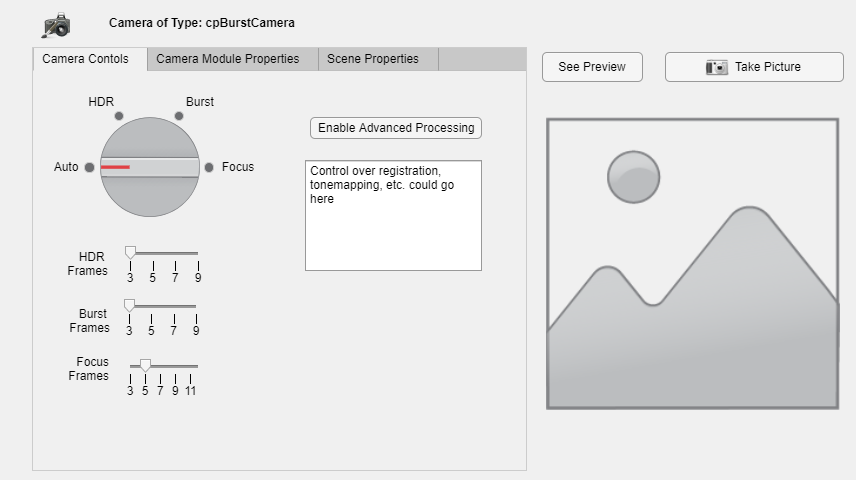

cpCameraWindow(ourCamera, pbrtCPScene);

## Take Pictures

burstImage = ourCamera.TakePicture(pbrtCPScene, 'Burst',...
    'numBurstFrames', 3, 'imageName','Burst',...
    'focusMode', 'Manual', 'focusParam', bDistance* 1.1, 'insensorIP',false);

Overwriting PBRT file C:\iset\iset3d\local\Cornell_BoxBunnyChart\tp35959834_4048_4b99_b401_3e489674df0e\Cornell_Box_Multiple_Cameras_Bunny_charts.pbrt
Elapsed time is 1.543623 seconds.
*** Rendering time for Cornell_Box_Multiple_Cameras_Bunny_charts:  142.0 sec ***

*** Rendering time for Cornell_Box_Multiple_Cameras_Bunny_charts_depth:  97.4 sec ***

Docker container vistalab/pbrt-v3-spectral:latest
Overwriting PBRT file C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts_depth.pbrt
Docker command
	docker run -ti --rm -w /Cornell_BoxBunnyChart -v C:/iset/iset3d/local/Cornell_BoxBunnyChart:/Cornell_BoxBunnyChart vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/Cornell_Box_Multiple_Cameras_Bunny_charts_depth.dat Cornell_Box_Multiple_Cameras_Bunny_charts_depth.pbrt
*** Rendering time for Cornell_Box_Multiple_Cameras_Bunny_charts_depth:  97.1 sec ***

  Reading image h=1024 x w=1024 x 31 spectral planes.
Overwriting PBRT file C:\iset\iset3d\local

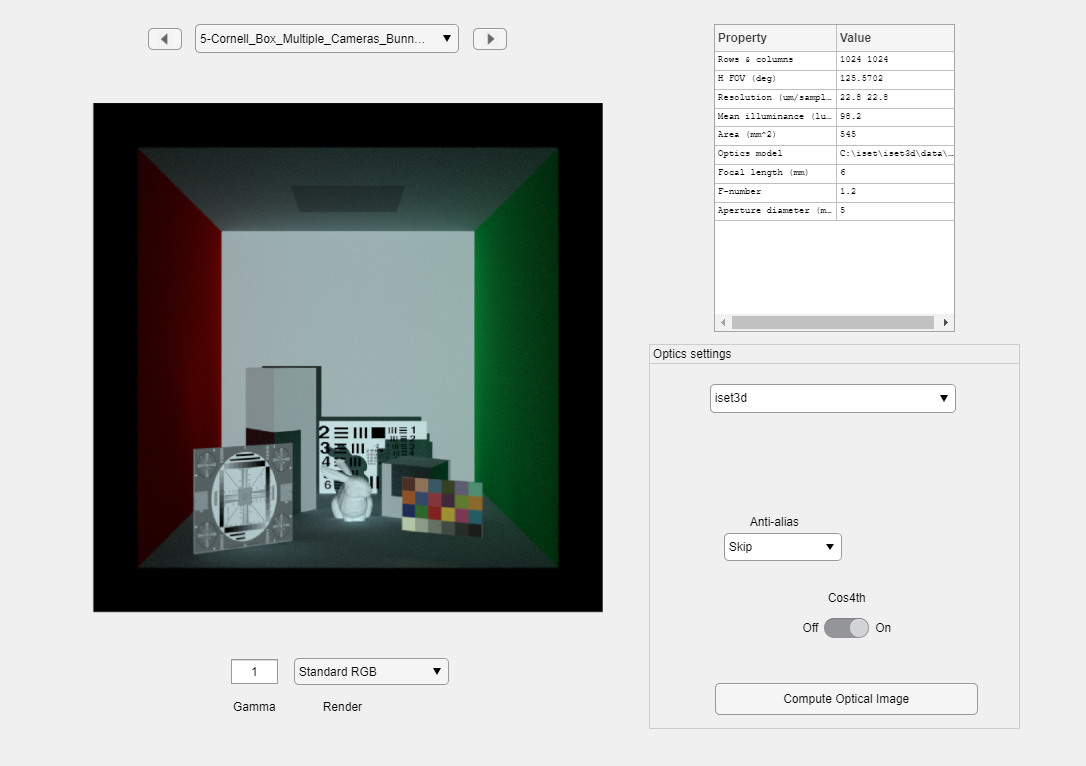

Overwriting PBRT file C:\iset\iset3d\local\Cornell_BoxBunnyChart\tp20013f85_850d_4c64_a538_562c6089b111\Cornell_Box_Multiple_Cameras_Bunny_charts.pbrt
Elapsed time is 1.295792 seconds.
*** Rendering time for Cornell_Box_Multiple_Cameras_Bunny_charts:  170.9 sec ***

*** Rendering time for Cornell_Box_Multiple_Cameras_Bunny_charts_depth:  121.6 sec ***



Docker container vistalab/pbrt-v3-spectral:latest
Overwriting PBRT file C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts_depth.pbrt
Docker command
	docker run -ti --rm -w /Cornell_BoxBunnyChart -v C:/iset/iset3d/local/Cornell_BoxBunnyChart:/Cornell_BoxBunnyChart vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/Cornell_Box_Multiple_Cameras_Bunny_charts_depth.dat Cornell_Box_Multiple_Cameras_Bunny_charts_depth.pbrt
*** Rendering time for Cornell_Box_Multiple_Cameras_Bunny_charts_depth:  115.3 sec ***

  Reading image h=1024 x w=1024 x 31 spectral planes.
Overwriting PBRT file C:\iset\iset3d\local\Cornell_BoxBunnyChart\tp0d6b4135_4331_401a_8877_bbc320d8d135\Cornell_Box_Multiple_Cameras_Bunny_charts.pbrt
Elapsed time is 1.472669 seconds.
*** Rendering time for Cornell_Box_Multiple_Cameras_Bunny_charts:  419.0 sec ***

*** Rendering time for Cornell_Box_Multiple_Cameras_Bunny_charts_depth:  124.1 sec ***

Overwriting PBRT file C:\iset\iset3d\loc

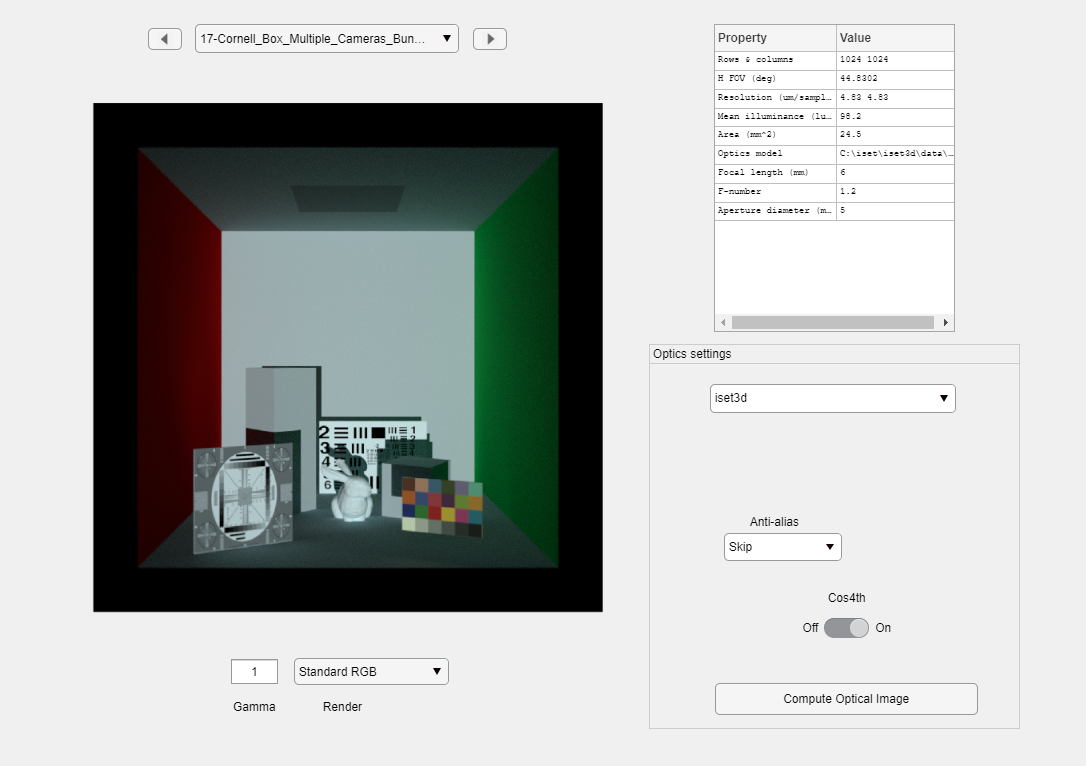

Fmeasure[100%]
SMeasure[100%]
Weights [100%]
Fusion [100%]

Elapsed time: 1.92 s:
Reading  (46.9%).
Fmeasure (38.9%).
SMeasure (7.1%).
Fusion   (7.2%).



stackedImage = ourCamera.TakePicture(pbrtCPScene, 'FocusStack', ...
    'focusMode', 'Stack', 'focusParam', 12, ...
    'imageName','Focus Stacked',...
    'insensorIP',false);

Overwriting PBRT file C:\iset\iset3d\local\Cornell_BoxBunnyChart\tp0e78a4f5_a80b_43e6_a65f_622f353b8ed8\Cornell_Box_Multiple_Cameras_Bunny_charts.pbrt
Elapsed time is 1.140838 seconds.
*** Rendering time for Cornell_Box_Multiple_Cameras_Bunny_charts:  517.2 sec ***

*** Rendering time for Cornell_Box_Multiple_Cameras_Bunny_charts_depth:  105.4 sec ***

Docker container vistalab/pbrt-v3-spectral:latest
Overwriting PBRT file C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts_depth.pbrt
Docker command
	docker run -ti --rm -w /Cornell_BoxBunnyChart -v C:/iset/iset3d/local/Cornell_BoxBunnyChart:/Cornell_BoxBunnyChart vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/Cornell_Box_Multiple_Cameras_Bunny_charts_depth.dat Cornell_Box_Multiple_Cameras_Bunny_charts_depth.pbrt
*** Rendering time for Cornell_Box_Multiple_Cameras_Bunny_charts_depth:  121.2 sec ***

  Reading image h=1024 x w=1024 x 31 spectral planes.
Overwriting PBRT file C:\iset\iset3d\loc

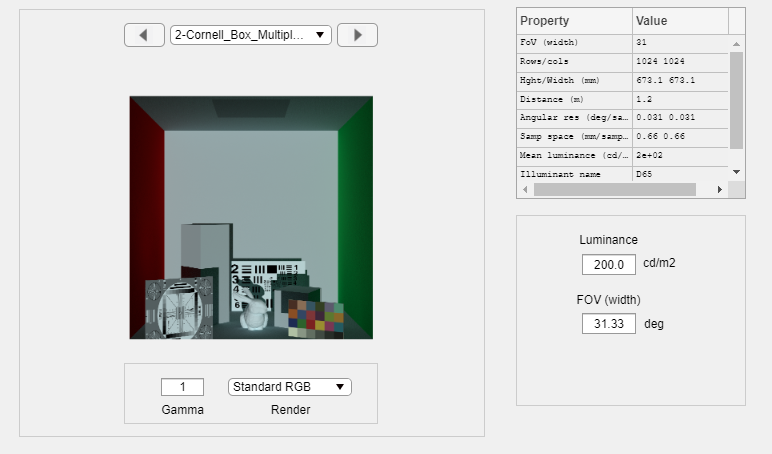


pinholeImage = pinholeCamera.TakePicture(pinholeCPScene, 'Auto',...
    'insensorIP', false);

Burst vs. Stacked with no motion

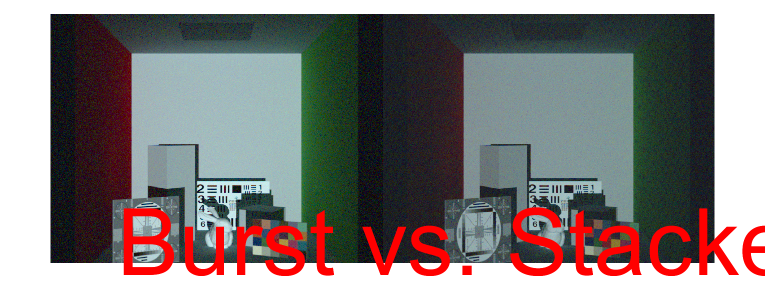


cpCompareImages(burstImage, stackedImage, 'Burst vs. Stacked with no motion');

Pinhole vs. Stacked with no motion

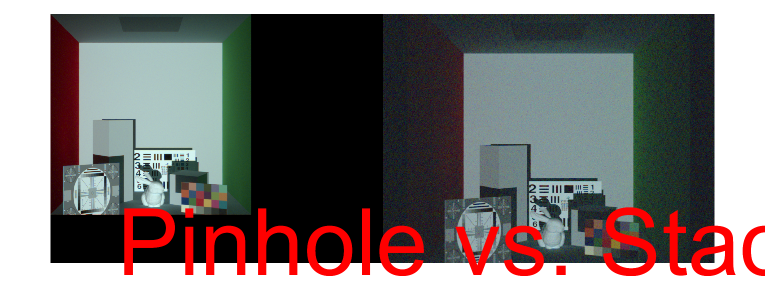

cpCompareImages(pinholeImage, stackedImage, 'Pinhole vs. Stacked with no motion');

Pinhole vs. Burst with no motion

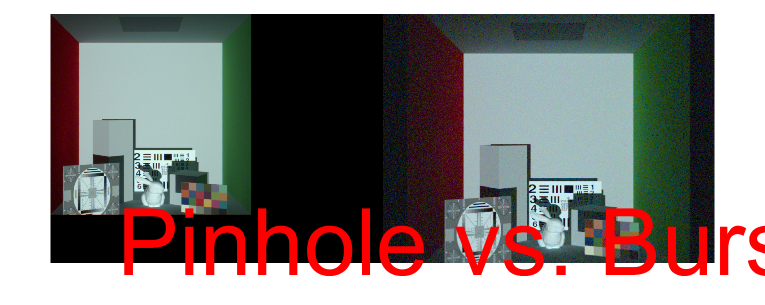

cpCompareImages(pinholeImage, burstImage, 'Pinhole vs. Burst with no motion');

## Print out some timing stats

Just for human consumption

tTotal = toc(getpref('ISET','tStart'));
afterTime = cputime;
beforeTime = getpref('ISET', 'benchmarkstart', 0);
glData = opengl('data');
disp(strcat("cpCompare ran  on: ", glData.Vendor, " ", glData.Renderer, "with driver version: ", glData.Version)); 

cpCompare ran  on: NVIDIA Corporation Quadro T2000/PCIe/SSE2with driver version: 4.6.0 NVIDIA 472.12


disp(strcat("cpCompare ran  in: ", string(afterTime - beforeTime), " seconds of CPU time."));

cpCompare ran  in: 2264.6406 seconds of CPU time.


disp(strcat("cpCompare ran  in: ", string(tTotal), " total seconds."));

cpCompare ran  in: 11432.3219 total seconds.
